# INF250 - CA3

### Upload your CA3_<your_mitt_id>.mlx submission on Mitt, make sure it is the correct version and double-check (for example by downloading and running it again) to make sure you submitted the right file!

During the third round of programming assignments, we focus on one hand on differences between linear interpolation, quadric interpolation and Hermite splines; and on the other hand on higher-order least-square approximations.

## Linear Interpolation, Quadric interpolation, Hermite Interpolation - 75% of the points:

Note that for this part of the assignment, you are NOT allowed to use any built-in MatLab functionality that could help you with the interpolation or spline generation!

For this part of the assignment you will try to make a flower/mandala drawing, using spline interpolation between a center point and points evenly distributed on a circle to draw petals. Spline interpolation is a great way to generate vertices (points) procedurally when making models in 2D and 3D, and these vertices can then be drawn lines between to make shapes and polygons.

**Hint:** *Have a look at the Matlab examples for the spline lectures (INF250-VisIntro-L3b-Splines--MATLAB) and try to really understand how they work - especially the piecewise and the Hermite example!*

**CIRCLE (5%)**

We start with generating points on a circle by using a parametric equation. Create an nx2 matrix C containing points on a circle surface, with n number of points and circle radius r.

**Hint: **[*https://doubleroot.in/lessons/circle/parametric-equation/*](https://doubleroot.in/lessons/circle/parametric-equation/)

clear;
close all;
C = [];                    % matrix (nx2) to store points on circle - one row is a 2D point (x,y)
nc = 24;                   % number of points on circle (we use n later, so lets call this nc instead)
r = 1;                     % radius of circle

func = linspace(0, 2*pi,nc+1)

func =          0    0.2618    0.5236    0.7854    1.0472    1.3090    1.5708    1.8326    2.0944    2.3562    2.6180    2.8798    3.1416    3.4034    3.6652    3.9270    4.1888    4.4506    4.7124    4.9742    5.2360    5.4978    5.7596    6.0214    6.2832



% Loop to generate points

C=zeros(nc,2)

C =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


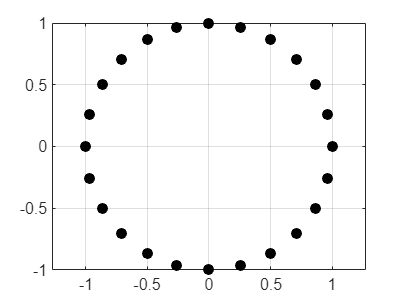

for i = 0 : nc-1
    C(i+1, 1) = r * cos(func(i+1)); % x-coordinate
    C(i+1, 2) = r * sin(func(i+1)); % y-coordinate
end

% draw a 2D scatter plot to see the points
figure(1);
plot(C(:,1), C(:,2), 'ko', 'MarkerFaceColor', 'k'), grid on, axis equal

**POINT (DRAW ORDER) MATRIX (5%)**

Even though we have the points on a circle, we need to generate another point matrix consisting of the "draw order" we will use when drawing the flower. The flower shall be drawn in the following manner: 

draw a line from the center to one point (p1). Then, draw a line from that point to a neighboring point (p2). Then draw a line back to the center. This makes up one "petal". Repeat this procedure until the flower has been completely filled with petals.

This point matrix can be used for both the linear spline interpolation and the quadric spline interpolation. For the Hermite spline you will need to make a new point matrix with a small adjustment.

**Hint: ***For each petal we need 3 points: the center point, and 2 points on the circle. Matrix p therefore needs to contain: center, one, two, center, two, three, center, three, four, etc. So, for each petal, we need: [center center] ; [p1 p1] ; [p2 p2] ; etc...*

center = [0,0];

p = zeros(3*nc,2);

for i = 1:nc
    p1_idx = i;
    p2_idx = mod(i, nc) + 1;

    p(3 * (i - 1) + 1, :) = center;
    p(3 * (i - 1) + 2, :) = C(p1_idx, :);
    p(3 * (i - 1) + 3, :) = C(p2_idx, :);
end




**PART 1: LINEAR SPLINE INTERPOLATION (20%)**

The first task will be to generate the interpolated points using linear interpolation. For each line in the draw order (for instance, a line between the center point and a point on the circle), you generate new points. These new points will define the final shape of each line, with the number of points used in each line defining its "resolution". The resolution does not matter much for linear spline interpolation since a straight line does not need more than two points to define it anyway, but once you start drawing curved lines later, it matters.

Set up an equation system -- one per coordinate:

1., no. of interpolants (per coordinate)

n = length(p(:,1))-1 

n = 71

2., seeking a linear interpolant of type $\mathbf{l}_i(t) = \mathbf{b}_i \cdot t + \mathbf{a}_i$, first, with two unknowns ($\mathbf{a}_i,\,\mathbf{b}_i\in\mathbb{R}^2$) per interpolant, leading to a vector of unknowns: $\left(\,\mathbf{a}_1^\top\,\,\,\mathbf{b}_1^\top\,\,\,\mathbf{a}_2^\top\,\,\,\mathbf{b}_2^\top\,\,\ldots\,\right)^\top$ $-$ per interpolant we get two equations:

- 
$$\mathbf{l}_i(0) = \mathbf{a}_i = \mathbf{p}_i$$


- 
$$\mathbf{l}_i(1) = \mathbf{b}_i + \mathbf{a}_i = \mathbf{p}_{i+1}$$


e = 2 % number of equations (per interpolant, per coordinate) 

e = 2

Let's set up the equation system:

A = zeros(e*n)    % empty matrix-setup

A =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

B = zeros(e*n, 2) % empty right-hand side 

B =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


Now, for each interpolant, fill in the two equations:

for i = 0:n-1
  % first equation per interpolant 
  A(1+2*i, 1+2*i) = 1; 
  B(1+2*i, :) = p(1+i, :); 
  % second equation per interpolant 
  A(2+2*i, 1+2*i) = 1; 
  A(2+2*i, 2+2*i) = 1; 
  B(2+2*i, :) = p(2+i, :); 
end

Let's look at the left-hand side and right-hand side of the equation system:

A % left-hand side

A =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     1     0     0     0     0     0     0     0     0     0     0     0   

B % right-hand side

B =          0         0
    1.0000         0
    1.0000         0
    0.9659    0.2588
    0.9659    0.2588
         0         0
         0         0
    0.9659    0.2588
    0.9659    0.2588
    0.8660    0.5000


Solve for the unknowns (per coordinate): 

**Hint: ***How do you solve for Ax = B?*

% solve for x
x = A\B;


Generate a new matrix with all the interpolated points:

**Hint:** *matrix x contains the factors of every line equation in the following form: *

*[xa ya *

* xb yb]*

%int_p is our matrix with interpolated points
resolution = 15;
FineLine = linspace(0, 1, resolution).'; 
int_p = zeros(n*resolution,2);

for i = 0:n-1
    tmp_points = x(1+2*i, :) + x(2+2*i, :).*FineLine;
    int_p((i)*resolution+1:(i+1)*resolution, :) = tmp_points;
end



Visualize:

**Hint: ***In a new figure:*

*1. Plot the original points on the circle*

*2. Draw the interpolated points.*

*3. Draw lines between the interpolated points.* 

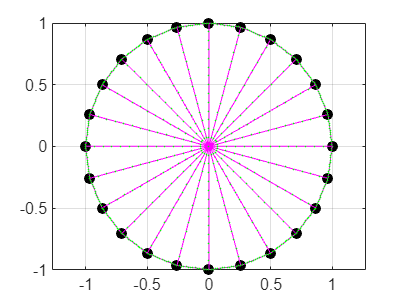

figure(2); 

%plot original points on the circle
plot (C(:,1), C(:,2), 'ko', 'MarkerFaceColor', 'k'), grid on, axis equal, hold on

for i = 1:length(int_p(:, 1)) - 1
    %draw interpolated points
    plot(int_p(:,1), int_p(:,2), 'g.', 'MarkerSize', 0.75)
    %draw lines between interpolated points
    plot([int_p(i, 1), int_p(i + 1, 1)], [int_p(i, 2), int_p(i + 1, 2)], 'm-')
end
hold off;

**PART 2: QUADRIC SPLINE INTERPOLATION (20%)**

For your second task, you will generate interpolated points using quadric spline interpolation. As in the previous task, generate new points between each point of the drawing order. This time the number of points used (the "resolution") will matter, since there will be curves. 

PS: This will not generate a "flower" since the quadric spline is quite unmanagable. Depending on the "missing equation", the curve will change dramatically. However, you can try to tame it and make it look like a nice "mandala" by adjusting the missing equation.

Set up an equation system -- one per coordinate:

1., no. of interpolants (per coordinate)

n = length(p(:,1))-1 

n = 71

 2., seeking a quadratic interpolant of type $\mathbf{q}_i(t) = \mathbf{c}_i \cdot t^2 + \mathbf{b}_i \cdot t + \mathbf{a}_i$ with three unknowns ($\mathbf{a}_i, \mathbf{b}_i, \mathbf{c}_i\in\mathbb{R}^2$) per interpolant, leading to a vector of unknowns: $\left(\,\mathbf{a}_1^\top\,\,\mathbf{b}_1^\top\,\,\mathbf{c}_1^\top\,\,\mathbf{a}_2^\top\,\,\mathbf{b}_2^\top\,\,\mathbf{c}_2^\top\,\,\ldots\,\right)^\top  $ $-$ per coordinate we get three equations:

- 
$$\mathbf{q}_i(0)  = \mathbf{a}_i             = \mathbf{p}_{i}$$


- 
$$\mathbf{q}_i(1)  = \mathbf{c}_i + \mathbf{b}_i + \mathbf{a}_i = \mathbf{p}_{i+1}$$


- $\mathbf{t}_i(1) = \mathbf{t}_{i+1}(0)$ with $\mathbf{t}_i(\tau) = \left.\frac{\mathrm{d}\mathbf{q}_i(u)}{\mathrm{d}u}\right|_\tau = 2\,\mathbf{c}_i\cdot\tau + \mathbf{b}_i$  and thus $2\,\mathbf{c}_i+\mathbf{b}_i-\mathbf{b}_{i+1}=0$

e = 3 % number of equations per interpolant and per coordinate 

e = 3

Setting up the equation system: 

A = zeros(e*n)    %% empty matrix-setup 

A =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

B = zeros(e*n, 2) %% empty setup of the right-hand side 

B =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


Now filling in the three equations for each interpolant: 

for i = 0:n-1
  % first equation per interpolant 
  A(1+e*i, 1+e*i) = 1; 
  B(1+e*i, :) = p(1+i, :); 
  % second equation per interpolant 
  A(2+e*i, 1+e*i) = 1; 
  A(2+e*i, 2+e*i) = 1; 
  A(2+e*i, 3+e*i) = 1; 
  B(2+e*i, :) = p(2+i, :); 
  % third equation per interpolant and per coordinate
  if i < n-1 
    A(3+e*i, 2+e*i) = 1; 
    A(3+e*i, 3+e*i) = 2; 
    A(3+e*i, 5+e*i) = -1; 
  else
    A(e*n, 2) = 1; 
  end
end

% choosing the "missing equation"
B(e*n, :) = [1.5 0.5]

B =          0         0
    1.0000         0
         0         0
    1.0000         0
    0.9659    0.2588
         0         0
    0.9659    0.2588
         0         0
         0         0
         0         0


Let's look at the left-hand side and right-hand side of the equation system:

A % left-hand side

A =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     2     0    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0   

B % right-hand side

B =          0         0
    1.0000         0
         0         0
    1.0000         0
    0.9659    0.2588
         0         0
    0.9659    0.2588
         0         0
         0         0
         0         0


Solve for the unknowns (per coordinate): 

**Hint: ***How do you solve for Ax = B?*

x = A \ B

x =          0         0
    1.5000    0.5000
   -0.5000   -0.5000
    1.0000         0
    0.5000   -0.5000
   -0.5341    0.7588
    0.9659    0.2588
   -0.5681    1.0176
   -0.3978   -1.2765
         0         0


Generate a new matrix with all the interpolated points:

**Hint:** *matrix x contains the factors of every line equation in the following form: *

[xa ya 

 xb yb

 xc yc]

resolution = 15;
FineLine = linspace(0, 1, resolution).'; 
int_p = zeros(n*resolution,2);

for i = 0:n-1
    tmp_points = x(1+3*i, :) + x(2+3*i, :).*FineLine + x(3+3*i, :).*FineLine.*FineLine;
    int_p((i)*resolution+1:(i+1)*resolution, :) = tmp_points;
end

Visualize:

**Hint: ***In a new figure:*

*1. Plot the original points on the circle*

*2. Draw the interpolated points.*

*3. Draw lines between the interpolated points.*

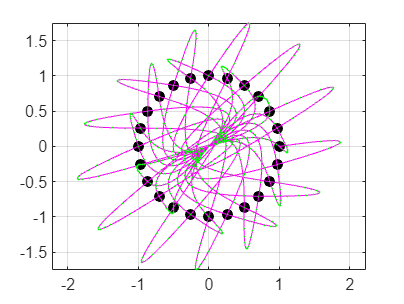

figure(3);

plot (C(:,1), C(:,2), 'ko', 'MarkerFaceColor', 'k'), grid on, axis equal, hold on

for i = 1:length(int_p(:, 1)) - 1
    %draw interpolated points
    plot(int_p(:,1), int_p(:,2), 'g.', 'MarkerSize', 0.75)
    %draw lines between interpolated points
    plot([int_p(i, 1), int_p(i + 1, 1)], [int_p(i, 2), int_p(i + 1, 2)], 'm-')
end
hold off;

**PART 3: HERMITE SPLINE INTERPOLATION (20%)**

For your third task, you will use Hermite spline interpolation. With the quadric interpolation, it is virtually impossible to generate something that looks like a flower, because each petal line equation is influenced by the other line equations. With a hermite spline, however, each line equation is independent, and this makes it much easier to manage the look of the drawing.

For this task, we will think about the draw instructions a little bit differently. For each line equation we need two points (start point and end point) and two tangents (start tangent and end tangent). You can generate these tangents however you like: in the following example I use the point position vectors themselves to generate the tangents.

The reason I added a "center-to-center" tangent vector is so that the p2-to-center line has an end tangent.

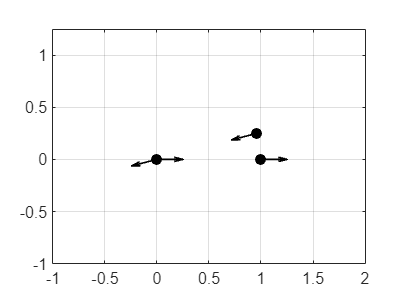

% Example points
ExPoints =  [[0.0 0.0] ;        %center
             [1.0 0.0] ;        %p1
             [0.96 0.25] ;      %p2
             [0.0 0.0] ];       %center

% Example tangents
ExTan =     [[1.0 0.0] ;        %center-to-p1 vector
             [1.0 0.0] ;        %p1-to-p2 vector
             [-0.96 -0.25] ;    %p2-to-center vector
             [-0.96 -0.25] ];   %center-to-center vector

% Scale the tangent vectors to get smaller arrows
% (remember: scaling the tangents will also affect the spline interpolation)
ExTan = ExTan*1/4;

% Plot example
figure(4);
plot (ExPoints(:,1), ExPoints(:,2), 'ko', 'MarkerFaceColor', 'k'), grid on, axis equal, hold on
axis([min(ExPoints(:,1))-1 max(ExPoints(:,1))+1 min(ExPoints(:,2))-1 max(ExPoints(:,2))+1])
xticks(min(ExPoints(:,1))-1:0.5:max(ExPoints(:,1))+1)
yticks(min(ExPoints(:,2))-1:0.5:max(ExPoints(:,2))+1)
quiver(ExPoints(:,1), ExPoints(:,2), ExTan(:,1), ExTan(:,2), 0, 'k', 'LineWidth', 1.0)
hold off

As explained over, this time we construct a new point matrix of "draw orders" to make up for the fact that we need that fourth tangent vector in each petal shape.

**Hint: ***For each petal we need 4 points: the center point, 2 points on the circle, then the center point again. Matrix p therefore needs to contain: center, one, two, center, center, two, three, center, center, three, four, center, etc. So, for each petal, we need: [center center] ; [p1 p1] ; [p2 p2] ; [center center] etc...*

%TODO
center = [0,0];
p = zeros(3*nc,2);

for i = 1:nc
    p1_idx = i;
    p2_idx = mod(i, nc) + 1;
    
    p(4 * (i - 1) + 1, :) = center;
    p(4 * (i - 1) + 2, :) = C(p1_idx, :);
    p(4 * (i - 1) + 3, :) = C(p2_idx, :);
    p(4 * (i - 1) + 4, :) = center;
end




Tangents for each point:

n = length(p(:,1))-1

n = 95

T = zeros(n+1,2);


%% change the tangents a bit for a "nicer" flowerrr

for i=1:n
    %use vectors from point i to i+1 as tangents
    T(i,:) = p(i+1, :) - p(i,:);
end

% scale them to 80% of original
T = T*0.8   

T =     0.8000         0
   -0.0273    0.2071
   -0.7727   -0.2071
         0         0
    0.7727    0.2071
   -0.0799    0.1929
   -0.6928   -0.4000
         0         0
    0.6928    0.4000
   -0.1271    0.1657


Let's have a look at the tangents:

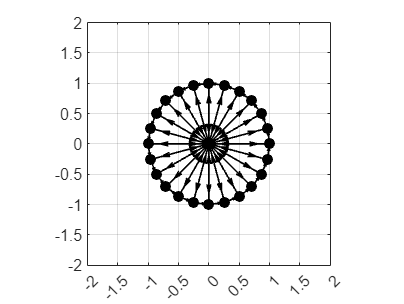

figure(5);
plot (p(:,1), p(:,2), 'ko', 'MarkerFaceColor', 'k'), grid on, axis equal, hold on
axis([min(p(:,1))-1 max(p(:,1))+1 min(p(:,2))-1 max(p(:,2))+1])
xticks(min(p(:,1))-1:0.5:max(p(:,1))+1)
yticks(min(p(:,2))-1:0.5:max(p(:,2))+1)
quiver(p(:,1), p(:,2), T(:,1), T(:,2), 0, 'k', 'LineWidth', 1.0)
hold off

Generate new matrix of interpolated points by Hermite interpolation between all the points in p (using tangents in T):

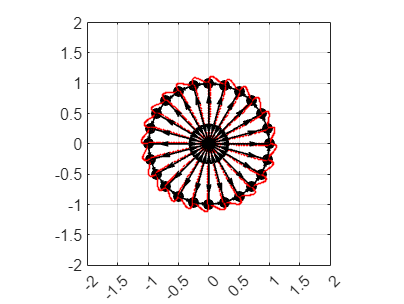

% Number of interpolation points
resolution = 50;

% Hermite interpolation function
M_H = [  2 -2  1  1; ...
         -3  3 -2 -1; ...
          0  0  1  0; ...
          1  0  0  0];
FineLine = linspace(0, 1, resolution).'; 
int_p = zeros(n*resolution,2);

for s = 1:n
    COEF = M_H * [p(s,:); p(s+1,:); T(s,:); T(s+1,:)];
    tmp_points = COEF(1,:).*power(FineLine,3) + COEF(2,:).*power(FineLine,2) + COEF(3,:).*FineLine + COEF(4,:); 
    int_p((s-1)*resolution+1:s*resolution, :) = tmp_points;
end


% Plot the interpolated points to see how they look
figure(6);
plot(p(:, 1), p(:, 2), 'ko', 'MarkerFaceColor', 'k'), grid on, axis equal, hold on
plot(int_p(:, 1), int_p(:, 2), 'r.', 'MarkerSize', 1)
axis([min(p(:, 1)) - 1, max(p(:, 1)) + 1, min(p(:, 2)) - 1, max(p(:, 2)) + 1])
xticks(min(p(:, 1)) - 1:0.5:max(p(:, 1)) + 1)
yticks(min(p(:, 2)) - 1:0.5:max(p(:, 2)) + 1)
quiver(p(:, 1), p(:, 2), T(:, 1), T(:, 2), 0, 'k', 'LineWidth', 1.0)
hold off

Visualize:

**Hint: ***In a new figure:*

*1. Plot the original points on the circle*

*2. Draw the interpolated points.*

*3. Draw lines between the interpolated points.*

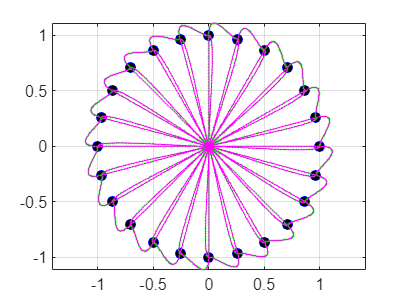

% Plot the original points on the circle
figure(7);
plot(C(:, 1), C(:, 2), 'bo', 'MarkerFaceColor', 'k'), grid on, axis equal, hold on

% Draw the interpolated points
plot(int_p(:, 1), int_p(:, 2), 'g.', 'MarkerSize', 1)

% Draw lines between the interpolated points
for i = 1:length(int_p(:, 1)) - 1
    plot([int_p(i, 1), int_p(i + 1, 1)], [int_p(i, 2), int_p(i + 1, 2)], 'm-')
end

hold off;

**ROTATION (5%)**

We can rotate all the tangents equally by using a rotation matrix. Using the given rotation matrix, recalculate the tangent matrix and store them in the same matrix (T):

angleRadians = pi/4;
rotMatrix = [cos(angleRadians) -sin(angleRadians); sin(angleRadians) cos(angleRadians)];
%TODO

for i = 1:n
    tangent = rotMatrix * T(i,:)';
    
    % Scale the tangent appropriately (optional)
    tangent = tangent' * 0.5; % Example scaling factor: 0.5
    
    % Store the tangent
    T(i, :) = tangent;

end


Let's have a look at them:

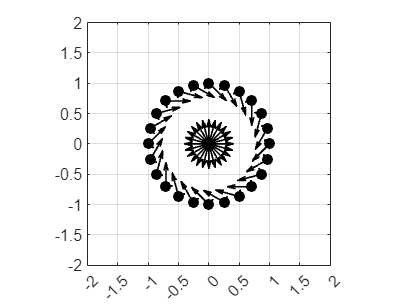

figure(8);
plot (p(:,1), p(:,2), 'ko', 'MarkerFaceColor', 'k'), grid on, axis equal, hold on
axis([min(p(:,1))-1 max(p(:,1))+1 min(p(:,2))-1 max(p(:,2))+1])
xticks(min(p(:,1))-1:0.5:max(p(:,1))+1)
yticks(min(p(:,2))-1:0.5:max(p(:,2))+1)
quiver(p(:,1), p(:,2), T(:,1), T(:,2), 0, 'k', 'LineWidth', 1.0)
hold off

Generate a new matrix of interpolated points using the rotated tangents:

%TODO

resolution = 50;

% Hermite interpolation function
M_H = [  2 -2  1  1; ...
         -3  3 -2 -1; ...
          0  0  1  0; ...
          1  0  0  0];
FineLine = linspace(0, 1, resolution).'; 
int_p = zeros(n*resolution,2);

for s = 1:n
    COEF = M_H * [p(s,:); p(s+1,:); T(s,:); T(s+1,:)];
    tmp_points = COEF(1,:).*power(FineLine,3) + COEF(2,:).*power(FineLine,2) + COEF(3,:).*FineLine + COEF(4,:); 
    int_p((s-1)*resolution+1:s*resolution, :) = tmp_points;
end


Visualize:

**Hint: ***In a new figure:*

*1. Plot the original points on the circle*

*2. Draw the interpolated points.*

*3. Draw lines between the interpolated points.*

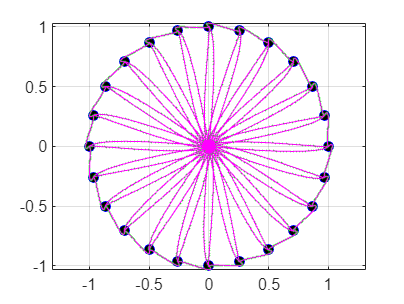

figure(9);
%TODO
plot(C(:, 1), C(:, 2), 'bo', 'MarkerFaceColor', 'k'), grid on, axis equal, hold on

% Draw the interpolated points
plot(int_p(:, 1), int_p(:, 2), 'g.', 'MarkerSize', 1)

% Draw lines between the interpolated points
for i = 1:length(int_p(:, 1)) - 1
    plot([int_p(i, 1), int_p(i + 1, 1)], [int_p(i, 2), int_p(i + 1, 2)], 'm-')
end

hold off;

## Least Square Approximation - 25% of the points:

In this part of the assignment we focus on higher order approximations (constant function, linear function, and quadratic approximation). Note that it is NOT allowed to use MATLABs *polyfit(...)* function. Instead, you should implement the necessary calculations "manually", but you are allowed to use *linsolve(...)*. 

*Hint:* *The MATLAB 'linsolve' functionality helps solving linear quations in matrix form*

Find a data set that you want to explore, which was not presented during the lectures or within the supplemental material that we provide in addition to the slides (such as the MATLAB files that are available on MITT). 

**Q: **Why is the data set you chose relevant and/or interesting to explore? What are your initial hypotheses about the data set?

***Answer: I chose a dataset that includes salary and years of experience from this link (https://www.kaggle.com/datasets/karthickveerakumar/salary-data-simple-linear-regression). I want to explore this dataset to see if there is any trend that can be plotted as a least squares approximation without much error. My hypothesis is that the higher years of experience the higher the salary. But is a linear approximation enough or do we need a quadratic approximation to get the best approximation.***

**Data set requirements: **

- the data should be in functional form (meaningful values corresponding to x and y coordinates)

- minimum number of values 30-50, do not aim for billions right away ;) 

*Hint: For the submission, load the data into your 'Workspace' and double-click on the (x and y) coordinates you want to use. In the new window called 'Variables' you can then mark a row or a column and copy it directly in a code-block within the live script. This way, you can assign variables in your code-block directly so that we can run the script without having to import any data. Do not forget to document the source of your data by adding a comment to the code where your data originates from.*

%T = readtable('Salary_Data.csv', 'NumHeaderLines',1);

TX = [1.10000000000000,1.30000000000000,1.50000000000000,2,2.20000000000000,2.90000000000000,3,3.20000000000000,3.20000000000000,3.70000000000000,3.90000000000000,4,4,4.10000000000000,4.50000000000000,4.90000000000000,5.10000000000000,5.30000000000000,5.90000000000000,6,6.80000000000000,7.10000000000000,7.90000000000000,8.20000000000000,8.70000000000000,9,9.50000000000000,9.60000000000000,10.3000000000000,10.5000000000000
];
TY = [39343,46205,37731,43525,39891,56642,60150,54445,64445,57189,63218,55794,56957,57081,61111,67938,66029,83088,81363,93940,91738,98273,101302,113812,109431,105582,116969,112635,122391,121872
];


Plot the input data and the resulting approximations as polynomial functions from above (a constant function, a linear function, and a quadratic approximation). Add a legend and axis lables that help understanding the plot. Make it visually expressive so that it can be understood by looking at it.

*Hint: The MATLAB 'scatter' functionality might be helpful to plot a scatter plot*

*Hint: The MATLAB 'polyval' functionality might be helpful to plot a function on polynomial form*

*Hint: The MATLAB 'hold on' and 'hold off' functionality might be useful to combine multiple plot(...) results into one summarizing plot.*

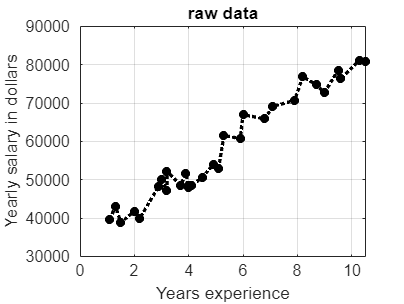

% First look at the data

figure(10);
plot (TX, TY, 'k:', 'LineWidth', 2), hold on, grid on, 
plot (TX, TY, 'ko', 'MarkerFaceColor', 'k', "MarkerSize", 5);
title('raw data');
xlabel('Years experience');
ylabel('Yearly salary in dollars');
set(gca, 'YTickLabel', get(gca, 'YTick'))
hold off

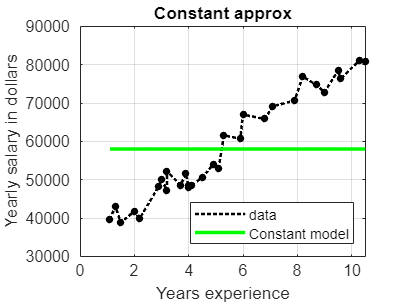



%Constant trend analysis

yConst = mean(TY);



%do linear trend analysis
nl = length(TY);

Bl = [sum(power(TX,2)), sum(TX); sum(TX), nl;];

zl = [sum(TY.*TX); ...
     sum(TY)]; 

cLin = Bl \ zl;


yLin = cLin(1)*TX + cLin(2); % evaluate the line

%Quadratic approx

nq = length(TY);

Bq = [sum(power(TX,4)), sum(power(TX,3)), sum(power(TX,2)); ...
     sum(power(TX,3)), sum(power(TX,2)), sum(TX); ...
     sum(power(TX,2)), sum(TX),          nq        ];

zq = [sum(TY.*power(TX,2)); ...
     sum(TY.*TX); ...
     sum(TY)]; 


cQuad = Bq \ zq; 

yQuad = cQuad(1)*power(TX,2) + cQuad(2)*TX + cQuad(3); % evaluate the line



%% Constant
figure(11);

p1 = plot (TX, TY, 'k:', "LineWidth", 1.5,  'DisplayName', 'data'); hold on, grid on, 
p2 = plot (TX, TY, 'ko', "MarkerFaceColor", "k", "MarkerSize", 4);
p3 = plot(TX, yConst * ones(size(TX)), 'g', 'LineWidth', 2, 'DisplayName', 'Constant model'); % plot constant approximation
legend([p1 p3],  "Location", "southeast");
title('Constant approx');
xlabel('Years experience');
ylabel('Yearly salary in dollars');
set(gca, 'YTickLabel', get(gca, 'YTick'))
hold off;

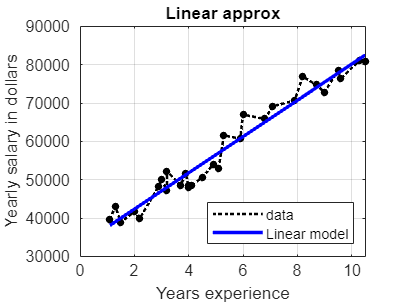



%%LINEAR
figure(12);

p1 = plot (TX, TY, 'k:', "LineWidth", 1.5,  'DisplayName', 'data'); hold on, grid on, 
p2 = plot (TX, TY, 'ko', "MarkerFaceColor", "k", "MarkerSize", 4); 
p3 = plot (TX, yLin, 'b-', "LineWidth", 2, 'DisplayName', 'Linear model');
legend([p1 p3],  "Location", "southeast");
title('Linear approx')
xlabel('Years experience');
ylabel('Yearly salary in dollars');
set(gca, 'YTickLabel', get(gca, 'YTick'))
hold off;

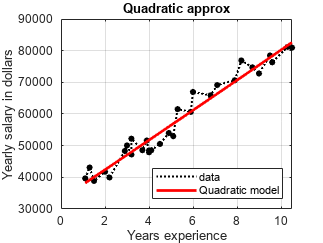


%%QUADRATIC
figure(13);

p1 = plot (TX, TY, 'k:', "LineWidth", 1.5,  'DisplayName', 'data'); hold on, grid on, 
p2 = plot (TX, TY, 'ko', "MarkerFaceColor", "k", "MarkerSize", 4); 
p4 = plot (TX, yQuad, 'r-' , "LineWidth", 2, 'DisplayName', 'Quadratic model'); 
legend([p1  p4],  "Location", "southeast");
title('Quadratic approx')
xlabel('Years experience');
ylabel('Yearly salary in dollars');
set(gca, 'YTickLabel', get(gca, 'YTick'))
hold off;

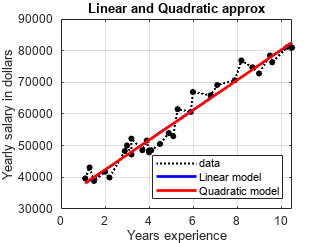



%%BOTH IN SAME PLOT
figure(14);

p1 = plot (TX, TY, 'k:', "LineWidth", 1.5,  'DisplayName', 'data'); hold on, grid on, 
p2 = plot (TX, TY, 'ko', "MarkerFaceColor", "k", "MarkerSize", 4); 
p3 = plot (TX, yLin, 'b-', "LineWidth", 2, 'DisplayName', 'Linear model');
p4 = plot (TX, yQuad, 'r-' , "LineWidth", 2, 'DisplayName', 'Quadratic model'); 
legend([p1 p3 p4],  "Location", "southeast");
title('Linear and Quadratic approx')
xlabel('Years experience');
ylabel('Yearly salary in dollars');
set(gca, 'YTickLabel', get(gca, 'YTick'))
hold off;

**Q: **Which approximation is the best, and why? Do you think any of the models can accurately describe the relationship between the two variables? Which insights about the data and the relationship between the variables did you discover?

***Answer: Both models are almost equal, infact we have to zoom in before we can see any actual difference between the linear and quadratic model. This can imply that the need for a quadratic model is not needed, and that the linear model is enough since we have quite a clear trend that salary goes up with more years of experience. It seems to increase about by 10000 dollars every year. ***

***I also discovered even with variations in the data points, the variations in salary are not big enough to impact the line in a big way. We can see this because the quadratic model is so similar to the linear model. So another thing to learn from this is that a quadratic model does not *****necessarily give a more accurate line.**

Now, for each approximation, remove a point that you consider to be the largest outlier relative to the fitted model (identified either by visual inspection or calculation). With this point removed, recalculate the three approximations. Next, do the same with a point that you consider to be very closely approximated by the model. So you end up with nine approximations: a constant, linear, and quadratic approximation of the whole data set, a contant, linerar, and quadratic approximation of the data set without the respective largest outlier, and a constant, linear, and quadratic approximation of the data set without the "best approximated" data point. Create three plots, one for the constant approximations, one for the linear approximations, and one for the quadratic approximations. Each should contain the data as a scatter plot and the three fitted models.

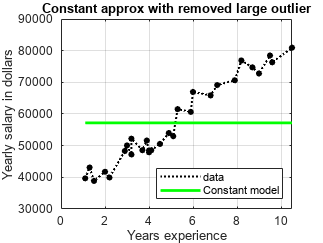

%%%%%%%%%%%%%% CONSTANT DATA SET WITHOUT LARGEST OUTLIER %%%%%%%%%%%%%%
%% remove point ?? x=10.3, y=122391

TXc = [1.10000000000000,1.30000000000000,1.50000000000000,2,2.20000000000000,2.90000000000000,3,3.20000000000000,3.20000000000000,3.70000000000000,3.90000000000000,4,4,4.10000000000000,4.50000000000000,4.90000000000000,5.10000000000000,5.30000000000000,5.90000000000000,6,6.80000000000000,7.10000000000000,7.90000000000000,8.20000000000000,8.70000000000000,9,9.50000000000000,9.60000000000000,10.5000000000000];

%Y value
TYc = [39343,46205,37731,43525,39891,56642,60150,54445,64445,57189,63218,55794,56957,57081,61111,67938,66029,83088,81363,93940,91738,98273,101302,113812,109431,105582,116969,112635,121872];


%%PLOT

yConstc = mean(TYc);

figure(15);
p1c = plot (TXc, TYc, 'k:', "LineWidth", 1.5,  'DisplayName', 'data'); hold on, grid on, 
p2c = plot (TXc, TYc, 'ko', "MarkerFaceColor", "k", "MarkerSize", 4);
p3c = plot(TXc, yConstc * ones(size(TXc)), 'g', 'LineWidth', 2, 'DisplayName', 'Constant model'); % plot constant approximation
legend([p1c p3c],  "Location", "southeast");
xlabel('Years experience');
ylabel('Yearly salary in dollars');
title('Constant approx with removed large outlier');
set(gca, 'YTickLabel', get(gca, 'YTick'))
hold off;

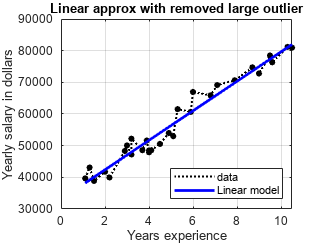



%%%%%%%%%%%%%% LINEAR DATA SET WITHOUT LARGEST OUTLIER %%%%%%%%%%%%%%
%remove point 24 x=8.2, y=113812

TXl = [1.10000000000000,1.30000000000000,1.50000000000000,2,2.20000000000000,2.90000000000000,3,3.20000000000000,3.20000000000000,3.70000000000000,3.90000000000000,4,4,4.10000000000000,4.50000000000000,4.90000000000000,5.10000000000000,5.30000000000000,5.90000000000000,6,6.80000000000000,7.10000000000000,7.90000000000000,8.70000000000000,9,9.50000000000000,9.60000000000000,10.3000000000000,10.5000000000000];

%Y value
TYl = [39343,46205,37731,43525,39891,56642,60150,54445,64445,57189,63218,55794,56957,57081,61111,67938,66029,83088,81363,93940,91738,98273,101302,109431,105582,116969,112635,122391,121872];

%%PLOT
nl = length(TYl);

Bl = [sum(power(TXl,2)), sum(TXl); sum(TXl), nl;];

zl = [sum(TYl.*TXl); ...
     sum(TYl)]; 

cLin = Bl \ zl;


yLinl = cLin(1)*TXl + cLin(2); % evaluate the line

figure(16);
p1l = plot (TXl, TYl, 'k:', "LineWidth", 1.5,  'DisplayName', 'data'); hold on, grid on, 
p2l = plot (TXl, TYl, 'ko', "MarkerFaceColor", "k", "MarkerSize", 4); 
p3l = plot (TXl, yLinl, 'b-', "LineWidth", 2, 'DisplayName', 'Linear model');
legend([p1l p3l],  "Location", "southeast");
title('Linear approx with removed large outlier')
xlabel('Years experience');
ylabel('Yearly salary in dollars');
set(gca, 'YTickLabel', get(gca, 'YTick'))
hold off;

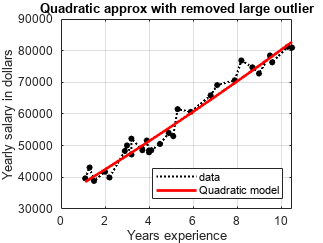


%%%%%%%%%%%%%% QUADRATIC DATA SET WITHOUT LARGEST OUTLIER %%%%%%%%%%%%%%
%% remove point 20 x=93940 and y=6.0


TXq = [1.10000000000000,1.30000000000000,1.50000000000000,2,2.20000000000000,2.90000000000000,3,3.20000000000000,3.20000000000000,3.70000000000000,3.90000000000000,4,4,4.10000000000000,4.50000000000000,4.90000000000000,5.10000000000000,5.30000000000000,5.90000000000000,6.80000000000000,7.10000000000000,7.90000000000000,8.20000000000000,8.70000000000000,9,9.50000000000000,9.60000000000000,10.3000000000000,10.5000000000000];

%Y value
TYq = [39343,46205,37731,43525,39891,56642,60150,54445,64445,57189,63218,55794,56957,57081,61111,67938,66029,83088,81363,91738,98273,101302,113812,109431,105582,116969,112635,122391,121872];


nq = length(TYq);

Bq = [sum(power(TXq,4)), sum(power(TXq,3)), sum(power(TXq,2)); ...
     sum(power(TXq,3)), sum(power(TXq,2)), sum(TXq); ...
     sum(power(TXq,2)), sum(TXq),          nq        ];

zq = [sum(TYq.*power(TXq,2)); ...
     sum(TYq.*TXq); ...
     sum(TYq)]; 


cQuad = Bq \ zq; 

yQuadq = cQuad(1)*power(TXq,2) + cQuad(2)*TXq + cQuad(3); % evaluate the line




figure(17);
p1q = plot (TXq, TYq, 'k:', "LineWidth", 1.5,  'DisplayName', 'data'); hold on, grid on, 
p2q = plot (TXq, TYq, 'ko', "MarkerFaceColor", "k", "MarkerSize", 4); 
p4q = plot (TXq, yQuadq, 'r-' , "LineWidth", 2, 'DisplayName', 'Quadratic model'); 
legend([p1q  p4q],  "Location", "southeast");
title('Quadratic approx with removed large outlier')
xlabel('Years experience');
ylabel('Yearly salary in dollars');
set(gca, 'YTickLabel', get(gca, 'YTick'))
hold off;

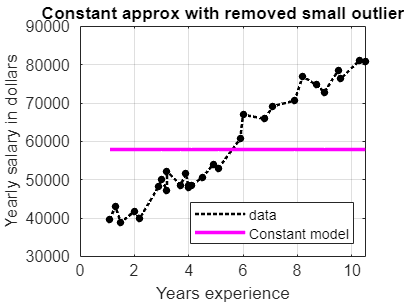





%%%%%%%%%%%%%% CONSTANT DATA SET WITHOUT SMALLEST OUTLIER %%%%%%%%%%%%%%

%% remove point x=5.3, y=83088

TXcc = [1.10000000000000,1.30000000000000,1.50000000000000,2,2.20000000000000,2.90000000000000,3,3.20000000000000,3.20000000000000,3.70000000000000,3.90000000000000,4,4,4.10000000000000,4.50000000000000,4.90000000000000,5.10000000000000,5.90000000000000,6,6.80000000000000,7.10000000000000,7.90000000000000,8.20000000000000,8.70000000000000,9,9.50000000000000,9.60000000000000,10.3000000000000,10.5000000000000];

%Y value
TYcc = [39343,46205,37731,43525,39891,56642,60150,54445,64445,57189,63218,55794,56957,57081,61111,67938,66029,81363,93940,91738,98273,101302,113812,109431,105582,116969,112635,122391,121872];

yConstcc = mean(TYcc);

figure(18);
p1cc = plot (TXcc, TYcc, 'k:', "LineWidth", 1.5,  'DisplayName', 'data'); hold on, grid on, 
p2cc = plot (TXcc, TYcc, 'ko', "MarkerFaceColor", "k", "MarkerSize", 4);
p3cc = plot(TXcc, yConstcc * ones(size(TXcc)), 'm', 'LineWidth', 2, 'DisplayName', 'Constant model'); % plot constant approximation
legend([p1cc p3cc],  "Location", "southeast");
xlabel('Years experience');
ylabel('Yearly salary in dollars');
title('Constant approx with removed small outlier');
set(gca, 'YTickLabel', get(gca, 'YTick'))
hold off;

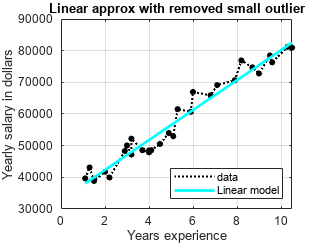


%%%%%%%%%%%%%% LINEAR DATA SET WITHOUT SMALLEST OUTLIER %%%%%%%%%%%%%%
% remove x=3.9 y=63218


TXll = [1.10000000000000,1.30000000000000,1.50000000000000,2,2.20000000000000,2.90000000000000,3,3.20000000000000,3.20000000000000,3.70000000000000,4,4,4.10000000000000,4.50000000000000,4.90000000000000,5.10000000000000,5.30000000000000,5.90000000000000,6,6.80000000000000,7.10000000000000,7.90000000000000,8.20000000000000,8.70000000000000,9,9.50000000000000,9.60000000000000,10.3000000000000,10.5000000000000];

%Y value
TYll = [39343,46205,37731,43525,39891,56642,60150,54445,64445,57189,55794,56957,57081,61111,67938,66029,83088,81363,93940,91738,98273,101302,113812,109431,105582,116969,112635,122391,121872];


%plot


nl = length(TYll);

Bll = [sum(power(TXll,2)), sum(TXll); sum(TXll), nl;];

zll = [sum(TYll.*TXll); ...
     sum(TYll)]; 

cLinl = Bll \ zll;


yLinll = cLinl(1)*TXll + cLinl(2); % evaluate the line

figure(18);
p1ll = plot (TXll, TYll, 'k:', "LineWidth", 1.5,  'DisplayName', 'data'); hold on, grid on, 
p2ll = plot (TXll, TYll, 'ko', "MarkerFaceColor", "k", "MarkerSize", 4); 
p3ll = plot (TXll, yLinll, 'c-', "LineWidth", 2, 'DisplayName', 'Linear model');
legend([p1ll p3ll],  "Location", "southeast");
title('Linear approx with removed small outlier')
xlabel('Years experience');
ylabel('Yearly salary in dollars');
set(gca, 'YTickLabel', get(gca, 'YTick'))
hold off;

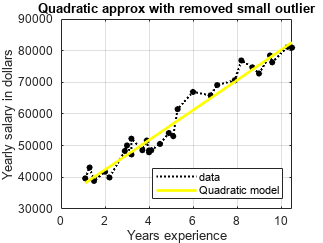












%%%%%%%%%%%%%% QUADRATIC DATA SET WITHOUT SMALLEST OUTLIER %%%%%%%%%%%%%%

%remove x = 5.9, y = 81363


TXqq = [1.10000000000000,1.30000000000000,1.50000000000000,2,2.20000000000000,2.90000000000000,3,3.20000000000000,3.20000000000000,3.70000000000000,3.90000000000000,4,4,4.10000000000000,4.50000000000000,4.90000000000000,5.10000000000000,5.30000000000000,6,6.80000000000000,7.10000000000000,7.90000000000000,8.20000000000000,8.70000000000000,9,9.50000000000000,9.60000000000000,10.3000000000000,10.5000000000000];

%Y value
TYqq = [39343,46205,37731,43525,39891,56642,60150,54445,64445,57189,63218,55794,56957,57081,61111,67938,66029,83088,93940,91738,98273,101302,113812,109431,105582,116969,112635,122391,121872];



nq = length(TYqq);

Bqq = [sum(power(TXqq,4)), sum(power(TXqq,3)), sum(power(TXqq,2)); ...
     sum(power(TXqq,3)), sum(power(TXqq,2)), sum(TXqq); ...
     sum(power(TXqq,2)), sum(TXqq),          nq        ];

zqq = [sum(TYqq.*power(TXqq,2)); ...
     sum(TYqq.*TXqq); ...
     sum(TYqq)]; 


cQuadq = Bqq \ zqq; 

yQuadqq = cQuadq(1)*power(TXqq,2) + cQuadq(2)*TXqq + cQuadq(3); % evaluate the line




figure(19);
p1qq = plot (TXqq, TYqq, 'k:', "LineWidth", 1.5,  'DisplayName', 'data'); hold on, grid on, 
p2qq = plot (TXqq, TYqq, 'ko', "MarkerFaceColor", "k", "MarkerSize", 4); 
p4qq = plot (TXqq, yQuadqq, 'y-' , "LineWidth", 2, 'DisplayName', 'Quadratic model'); 
legend([p1qq  p4qq],  "Location", "southeast");
title('Quadratic approx with removed small outlier')
xlabel('Years experience');
ylabel('Yearly salary in dollars');
set(gca, 'YTickLabel', get(gca, 'YTick'))
hold off;

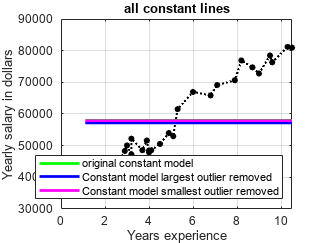



%%%NOW LETS COMPARE ALL THE LINES

%%%%CONSTANT LINES
figure(20);
p1 = plot (TXqq, TYqq, 'k:', "LineWidth", 1.5,  'DisplayName', 'data'); hold on, grid on, 
p2 = plot (TXqq, TYqq, 'ko', "MarkerFaceColor", "k", "MarkerSize", 4);
%%original line with all points
p3 =  plot(TX, yConst * ones(size(TX)), 'g', 'LineWidth', 2, 'DisplayName', 'original constant model'); % plot constant approximation
%%with largest outlier removed
p3c = plot(TXc, yConstc * ones(size(TXc)), 'b', 'LineWidth', 2, 'DisplayName', 'Constant model largest outlier removed'); % plot constant approximation
%%with smallest outlier removed
p3cc = plot(TXcc, yConstcc * ones(size(TXcc)), 'm', 'LineWidth', 2, 'DisplayName', 'Constant model smallest outlier removed'); % plot constant approximation


legend([p3  p3c p3cc],  "Location", "southeast");
title('all constant lines')
xlabel('Years experience');
ylabel('Yearly salary in dollars');
set(gca, 'YTickLabel', get(gca, 'YTick'))
hold off;

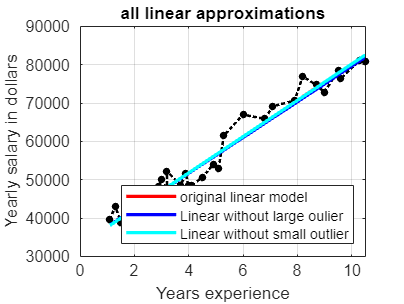


%%%LINEAR LINES
figure(21);
p1 = plot (TXqq, TYqq, 'k:', "LineWidth", 1.5,  'DisplayName', 'data'); hold on, grid on, 
p2 = plot (TXqq, TYqq, 'ko', "MarkerFaceColor", "k", "MarkerSize", 4);
%%original line with all points
p3 = plot (TX, yLin, 'r-', "LineWidth", 2, 'DisplayName', 'original linear model');
%%with largest outlier removed
p3l = plot (TXl, yLinl, 'b-', "LineWidth", 2, 'DisplayName', 'Linear without large oulier');%%with smallest outlier removed
p3ll = plot (TXll, yLinll, 'c-', "LineWidth", 2, 'DisplayName', 'Linear without small outlier');


legend([p3  p3l p3ll],  "Location", "southeast");
title('all linear approximations')
xlabel('Years experience');
ylabel('Yearly salary in dollars');
set(gca, 'YTickLabel', get(gca, 'YTick'))
hold off;

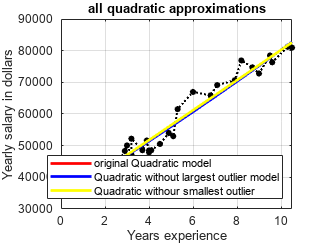




%%QUADRATIC LINES

figure(21);
p1 = plot (TXqq, TYqq, 'k:', "LineWidth", 1.5,  'DisplayName', 'data'); hold on, grid on, 
p2 = plot (TXqq, TYqq, 'ko', "MarkerFaceColor", "k", "MarkerSize", 4);
%%original line with all points
p3 = plot (TX, yQuad, 'r-' , "LineWidth", 2, 'DisplayName', 'original Quadratic model'); 
%%with largest outlier removed
p3q = plot (TXq, yQuadq, 'b-' , "LineWidth", 2, 'DisplayName', 'Quadratic without largest outlier model');
p3qq =plot (TXqq, yQuadqq, 'y-' , "LineWidth", 2, 'DisplayName', 'Quadratic withour smallest outlier'); 


legend([p3  p3q p3qq],  "Location", "southeast");
title('all quadratic approximations')
xlabel('Years experience');
ylabel('Yearly salary in dollars');
set(gca, 'YTickLabel', get(gca, 'YTick'))




hold off;

**Q: **Which type of approximation is the most robust against missing data points, and why do you think this is the case?

***Answer:  Looking at all the models it is not that simple to say, but if we choose a point lets say x=6 and then compare the lines we can see that the quadratic approximation has the least amount of change between the original line and the line that is missing the smallest outlier where we only have a difference in y value of 4.2. This might be the case because it is the highest order approximation, and with higher order of approximation the more robbust our model becomes***

**Q: **What influenced the model the most, removing an outlier or removing a "best approximated" point? Why? Is it different in the different types of approximations? 

***Answer: In all of the approximations it seems that removing the largest outlier affects the line the most, i think this makes sense because the bigger the outlier the more the line has to change to account for that, while with a small outlier the line does not have to account that much. It is not different in any of the models, but the magnitude of change is a bit diferrent where the constant and quadratic lines were most affected by removing the biggest outlier while the linear approximation was not affected as much.***